clear all;

%x = featureExtract("Data/genres_original/blues/blues.00000.wav")
for ii = 0:99
    A = sprintf('Data/genres_original/rock/rock.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+1,:) = feature;
    label(ii+1) = "rock";
end
for ii = 0:99
    A = sprintf('Data/genres_original/classical/classical.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+101,:) = feature;
    label(ii+101) = "classical";
end
for ii = 0:99
    A = sprintf('Data/genres_original/pop/pop.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+201,:) = feature;
    label(ii+201) = "pop";
end
for ii = 0:99
    A = sprintf('Data/genres_original/metal/metal.%05d.wav', ii);
    feature = featureExtract(A);
    features(ii+301,:) = feature;
    label(ii+301) = "metal";
end

trainingVector = randi([1 400], [350 1]);
for ii = 1:350
    trainingDataset(ii,:) = features(trainingVector(ii),:);
    trainingLabel(ii) = label(trainingVector(ii));
end

testingVector = randi([1 400], [50 1]);
for ii = 1:50
    testingDataset(ii, :) = features(testingVector(ii),:);
    testingLabel(ii) = label(testingVector(ii));
end
trainingLabelCategorical = categorical(trainingLabel');
testingLabelCategorical = categorical(testingLabel');

layers = [
    featureInputLayer(56)
    fullyConnectedLayer(32)
    reluLayer
    fullyConnectedLayer(16)
    reluLayer
    fullyConnectedLayer(4)
    softmaxLayer
    classificationLayer
];

options = trainingOptions("adam", ...
    InitialLearnRate=0.001, ...
    MaxEpochs=1000, ...
    Shuffle="every-epoch", ...
    ValidationData={testingDataset,testingLabelCategorical}, ...
    ValidationFrequency=3);
net = trainNetwork(trainingDataset,trainingLabelCategorical,layers,options);

Training on single CPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       29.69% |       32.00% |       4.7191 |       4.3322 |          0.0010 |
|       2 |           3 |       00:00:00 |       21.88% |       32.00% |       4.6847 |       3.7599 |          0.0010 |
|       3 |           6 |       00:00:00 |       29.69% |       32.00% |       3.5578 |       2.9531 |          0.0010 |
|       5 |           9 |       00:00:00 |       19.53% |       32.00% |       3.1972 |       2.2744 |          0.0010 |
|       

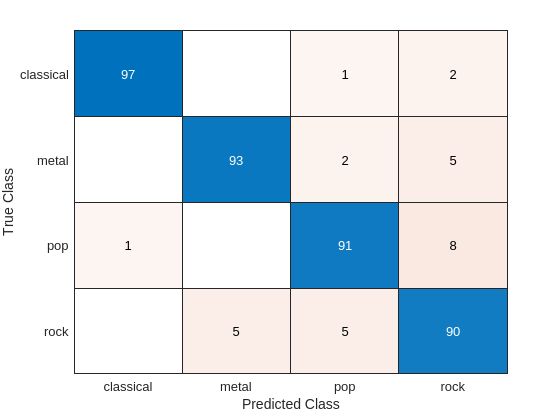

guess = zeros(400,1);
for ii = 1:400
    predictions(ii,:) = predict(net, features(ii,:));
    [maxVals(ii), guess(ii)] = max(predictions(ii,:));
end

for ii = 1:400
    if guess(ii) == 1
        predictedLabel(ii) = "classical";
    end
    if guess(ii) == 2
        predictedLabel(ii) = "metal";
    end
    if guess(ii) == 3
        predictedLabel(ii) = "pop";
    end
    if guess(ii) == 4
        predictedLabel(ii) = "rock";
    end
end
confusionchart(label, predictedLabel)

function  featureVector = featureExtract(x)

    % Step 1: Specify the WAV file
    
    filename = x;
    
    % Check if file exists
    if ~isfile(filename)
        error('File does not exist. Check the filename and try again.');
    end
    
    % Read the audio file
    [audioIn, fs] = audioread(filename);
    % Convert mono if it's stereo
    if size(audioIn, 2) > 1
        audioIn = mean(audioIn, 2);  % Convert to mono by averaging channels
    end
    
   
    
    % Compute MFCCs, delta, and delta-delta
    [coeffs, ~, ~, ~] = mfcc(audioIn, fs, 'NumCoeffs', 13);
    
    % Compute delta and delta-delta
    delta = diff(coeffs, 1, 1);
    deltaDelta = diff(delta, 1, 1);
    
    % Prepare to compute statistics
    coeffs_stats = [coeffs; delta; deltaDelta];
    
    % Calculate the mean, variance, max, and min
    mean_coeffs = mean(coeffs_stats, 1);
    var_coeffs = var(coeffs_stats, 0, 1);
    max_coeffs = max(coeffs_stats, [], 1);
    min_coeffs = min(coeffs_stats, [], 1);

    featureVector = [mean_coeffs, var_coeffs, max_coeffs, min_coeffs];
end